# Project

warning('off')

Configuration Parameters

% Initial cube configuration
Tsc_initial = [1, 0, 0, 1; 0, 1, 0, 0; 0, 0, 1, 0.025; 0, 0, 0, 1];

% Final cube configuration  
Tsc_final = [0, 1, 0, 0; -1, 0, 0, -1; 0, 0, 1, 0.025; 0, 0, 0, 1];

% End-effector grasp configuration relative to cube
Tce_grasp = [0, 0, 1, 0; 0, 1, 0, 0; -1, 0, 0, 0.01; 0, 0, 0, 1];

% End-effector standoff configuration relative to cube
Tce_standoff = [0, 0, 1, 0; 0, 1, 0, 0; -1, 0, 0, 0.1; 0, 0, 0, 1];

% Initial end-effector configuration
Tse_initial = [0, 0, 1, 0; 0, 1, 0, 0; -1, 0, 0, 0.5; 0, 0, 0, 1];

% Number of trajectory points per 0.01 seconds
k = 1;

% Initial robot configuration [phi, x, y, J1, J2, J3, J4, J5, W1, W2, W3, W4]
initial_config = [0,0,0,0,0,0,0,0,0,0,0,0];
%initial_config =  [-pi/6, 0, 0, 0.1, 0.2, -0.5, -0.7, 0, 0, 0, 0, 0];
% Control parameters
timestep = 0.01;
ControlLimit = 10; % Maximum joint/wheel velocity

% Feedback control gains
Kp = 25 * eye(6);
Ki = 4 * eye(6);
Kd = 2 * eye(6); 

% Chassis parameters
r = 0.0475; % Wheel radius (m)
l = 0.235;  % Half distance between front/back wheels (m)
w = 0.15;   % Half distance between left/right wheels (m)
h = 0.0963; % Height of chassis frame above ground (m)

Tb0 = [1, 0, 0, 0.1662; 0, 1, 0, 0; 0, 0, 1, 0.0026; 0, 0, 0, 1];
M0e = [1, 0, 0, 0.033; 0, 1, 0, 0; 0, 0, 1, 0.6546; 0, 0, 0, 1];

% Screw axes in end-effector frame
Blist = [0, 0, 1, 0, 0.033, 0;
         0, -1, 0, -0.5076, 0, 0;
         0, -1, 0, -0.3526, 0, 0;
         0, -1, 0, -0.2176, 0, 0;
         0, 0, 1, 0, 0, 0]';

Generating Reference Trajectory

fprintf('Generating reference trajectory...\n');

Generating reference trajectory...


trajectory = TrajectoryGenerator(Tse_initial, Tsc_initial, Tsc_final, Tce_grasp, Tce_standoff, k);
fprintf('Reference Trajectory Successfully generated ! \n');

Reference Trajectory Successfully generated ! 


Main Control Loop

fprintf('Starting control simulation...\n');

Starting control simulation...


config = initial_config;
N = size(trajectory, 1);
configurations = zeros(N, 13);
error_log = zeros(N, 6);
integralError = zeros(6, 1);
derivError = zeros(6, 1);
filteredDerivativeError = zeros(6,1);
alpha=0.535;
for i = 1:N-1
    % Current reference configuration Xd
    Xd = [[trajectory(i,1:3);trajectory(i,4:6);trajectory(i,7:9);0 0 0] [ trajectory(i,10:12)' ; 1]];
    
    % Next reference configuration Xd_next
    if i < N
        Xd_next = [[trajectory(i+1,1:3);trajectory(i+1,4:6);trajectory(i+1,7:9);0 0 0] [ trajectory(i+1,10:12)' ; 1]];
    else
        Xd_next = Xd;
    end
    
    % Current actual end-effector configuration X 
    X = getCurrentEndEffectorConfiguration(config, Tb0, M0e, Blist);
    
    % Calculate feedback control
    [V, integralError,derivError,filteredDerivativeError] = FeedbackControl(X, Xd, Xd_next, Kp, Ki,Kd, timestep, integralError,derivError, filteredDerivativeError,alpha);
    
    %Calculating Jacobian in order to evaluate and control variables
    Je = calculateJacobian(config, Tb0, M0e, Blist);
    controls = pinv(Je, 1e-4) * V; % Using tolerance of 1e-3
    u = controls(1:4);        % Wheel velocities
    theta_dot = controls(5:9); % Joint velocities
    
    % Calculating next state configuration
    config = NextState(config, u', theta_dot', timestep, ControlLimit);
    
    % Storing configuration and error
    configurations(i, :) = [config, trajectory(i, 13)]; 
    Xerr = MatrixLog6(X^-1 * Xd);
    error_log(i, :) = se3ToVec(Xerr)';
    
end

fprintf('Simulation Complete ! \n');

Simulation Complete ! 


Saving Results

fprintf('Saving results...\n');

Saving results...



% Saving CSV configurations file for CoppeliaSim
csvwrite('config.csv', configurations);

% Saving error log to visualize decrement in error
csvwrite('error.csv', error_log);

Visualizing Error

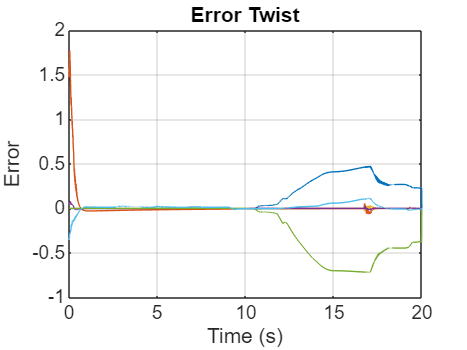

figure;
plot(0:timestep:(N-1)*timestep, error_log);
xlabel('Time (s)');
ylabel('Error');
title('Error Twist');
%legend('wx', 'wy', 'wz', 'vx', 'vy', 'vz');
grid on;